v_air  = out.logsout.get("v_AirspeedSensor").Values.Data;
v_real = out.logsout.get("v").Values.Data;
a_acc  = out.logsout.get("a_Acc").Values.Data;

t  = out.logsout.get("v").Values.Time;
dt = mean(diff(t));

R_base = var(v_air - v_real);

Q_values = [0.1 1 5 10 25 50 100];
threshold_values = [10 20 30 40];

best_rmse = inf;

for qi = 1:length(Q_values)

    Q = Q_values(qi);

    for ti = 1:length(threshold_values)

        threshold = threshold_values(ti);

        v_est = zeros(size(v_real));
        P = 10;
        v_est(1) = v_air(1);

        for k = 2:length(v_real)

            % Prediction with accelerometer
            v_pred = v_est(k-1) + a_acc(k)*dt;
            P_pred = P + Q;

            % Innovation
            innovation = v_air(k) - v_pred;

            % Adaptive measurement noise
            if abs(innovation) > threshold
                R_use = 100 * R_base;   % airspeed unreliable
            else
                R_use = R_base;         % airspeed normal
            end

            % Kalman update
            K = P_pred / (P_pred + R_use);

            v_est(k) = v_pred + K * innovation;
            P = (1 - K) * P_pred;

        end

        rmse = sqrt(mean((v_est - v_real).^2));

        if rmse < best_rmse
            best_rmse = rmse;
            best_Q = Q;
            best_threshold = threshold;
            best_v_est = v_est;
        end

    end
end

rmse_air = sqrt(mean((v_air - v_real).^2));

fprintf("Airspeed RMSE = %.3f m/s\n", rmse_air);

Airspeed RMSE = 23.694 m/s


fprintf("Best Kalman RMSE = %.3f m/s\n", best_rmse);

Best Kalman RMSE = 23.688 m/s


fprintf("Best Q = %.3f\n", best_Q);

Best Q = 0.100


fprintf("Best threshold = %.3f m/s\n", best_threshold);

Best threshold = 30.000 m/s


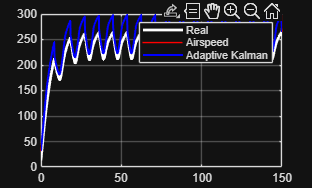


figure
plot(t, v_real, 'w', 'LineWidth', 2)
hold on
plot(t, v_air, 'r')
plot(t, best_v_est, 'b', 'LineWidth', 1.5)
legend('Real','Airspeed','Adaptive Kalman')
grid on